clear all

syms t

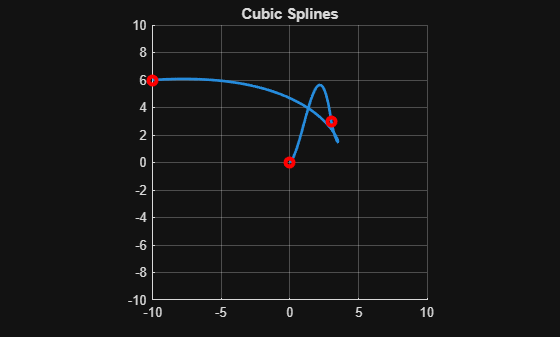

tVect = [1, t, t^2, t^3];
noSegments = 2;

for i = 1:(3 * noSegments + 1)
    points = [unifrnd(-10,10), unifrnd(-10,10)];
    allPoints(i,:) = points;
end

%allPoints = [0,0; 1,1; 2,10; 3,3; 4,-2; 5,7; -10,6; -3,-6];
bezierTraj = [];
segments = [];
i = 1;

while i < size(allPoints,1) - mod(size(allPoints, 1) - 1,3)
    p1 = allPoints(i,:);
    p2 = allPoints(i+1,:);
    p3 = allPoints(i+2,:);
    p4 = allPoints(i+3,:);
    controlPoints = [p1; p2; p3; p4]; % P1 & P4 are endpoints, P2 & P3 are control points
    j = size(segments,2);
    segments(:,[j+1, j+2]) = controlPoints;
    i = i + 3;
end

% Bezier
bezChar = [1, 0, 0, 0; 
    -3, 3, 0, 0;
    3, -6, 3, 0;
    -1, 3, -3, 1];
timeSteps = 50;
time = linspace(0,1,timeSteps);
path = [];

for k = 1:2:size(segments,2)
    controlPoints = segments(:, k:k+1);
    bezierCurve = tVect * bezChar * controlPoints;

    % Simulation
    curves = bezierCurve;
    segTraj = zeros(length(time), length(curves));
    for i = 1:length(time)
        for j = 1:length(curves)
            point = subs(curves(j), t, time(i));
            segTraj(i, j) = point;
        end
    end
    l = size(path,1);
    path(l+1:l+timeSteps, :) = segTraj;
end

path;

% Plot
hold on
title("Cubic Splines")
%plot(controlPoints([1,2],1), controlPoints([1,2],2), 'g--', 'LineWidth', 1)
%plot(controlPoints([4,3],1), controlPoints([4,3],2), 'g--', 'LineWidth', 1)
%plot(controlPoints([2,3],1), controlPoints([2,3],2), 'go', 'LineWidth', 1)
plot(path(:,1), path(:,2), 'LineWidth', 2)

knots = segments([1,4],:);
plot([knots(1, 1:2:length(knots)), knots(2, end-1)], [knots(1, 2:2:length(knots)), knots(2, end)], 'ro', 'LineWidth', 3)
axis equal
xlim([-10,10]);
ylim([-10,10]);
grid on
hold off